% Open Image Labeler
% Make pixel labels, e.g., "NotEye" and "Eye"

% Import image from file (Label tab).

% Label all pixels as "NotEye": click on NotEye, then shift-click image.
% Select "Eye" pixel label and use tools (e.g., brush) to select pixels.

% Under Label tab, save session and export labels to file.
% See subdirectory PixelLabelData.
% Categorical matrix is in png format as Label_#.png. 
% Largest # has a png matrix of the same size as the original image.
% Background == 2; Eye == 1;

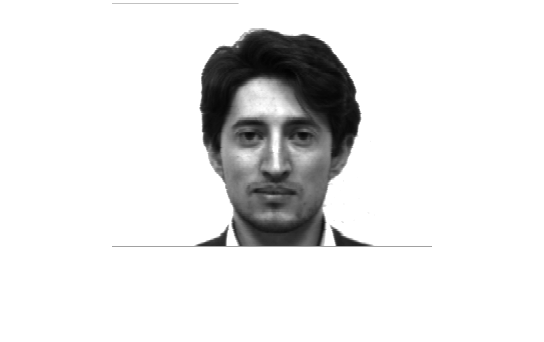

% View original image:
[X,map] = imread('/Users/vhowle/Projects/ML_Eyes/DataImages/subject03.normal.gif');
imshow(X,map)

disp(sprintf('Size of image = %g x %g', size(X,1), size(X,2)));

Size of image = 243 x 320


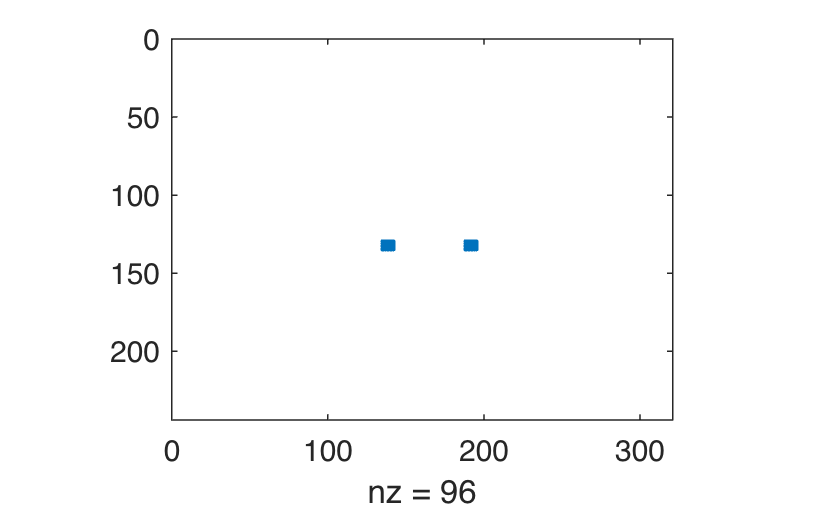

% To convert to a matrix of zeros and ones:
A = imread('/Users/vhowle/Projects/ML_Eyes/PixelLabelData_11/Label_2.png', 'png');
[row, col] = find(A == 2);
B = zeros(size(X,1), size(X,2));
B(row,col) = 1;
spy(B)

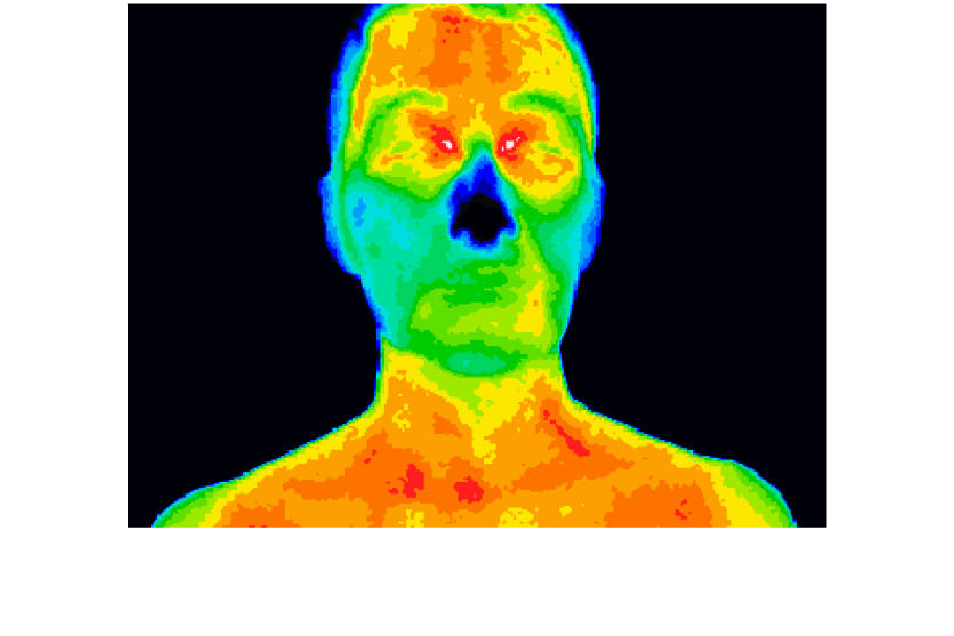

% Thermal image:
[X,map] = imread('/Users/vhowle/Projects/ML_Eyes/DataImages/istockphoto-911128564-612x612.jpg');
imshow(X,map)

disp(sprintf('Size of image = %g x %g', size(X,1), size(X,2)));

Size of image = 459 x 612


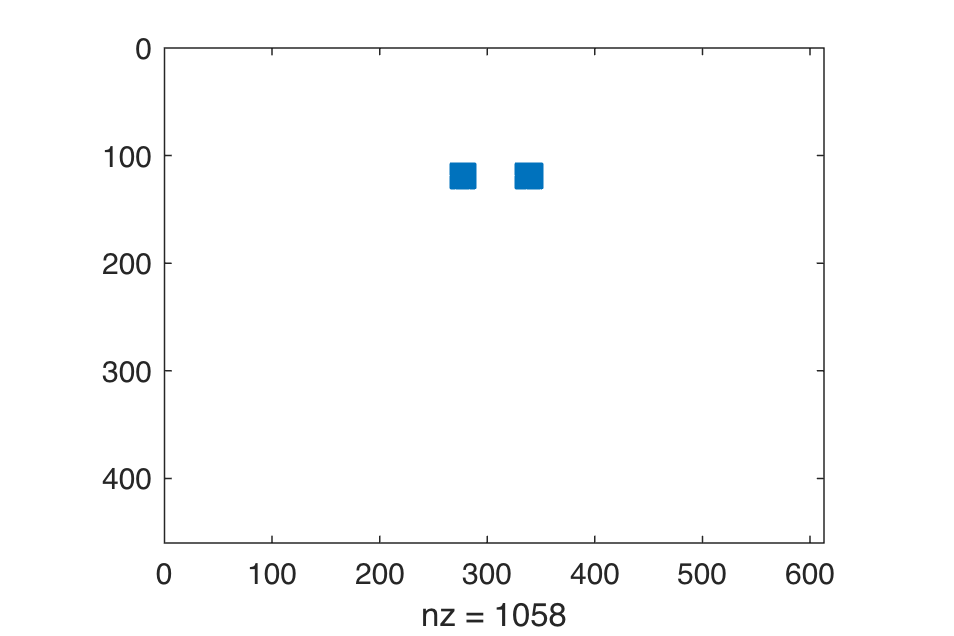

% To convert to a matrix of zeros and ones:
A = imread('/Users/vhowle/Projects/ML_Eyes/PixelLabelData_9/Label_1.png', 'png');
[row, col] = find(A == 2);
B = zeros(size(X,1), size(X,2));
B(row,col) = 1;
spy(B)